# Examples 3.5 and 3.7: Empirical Joint and Marginal Pdfs of Flow Cytometer

Note: this script reproduces Examples 3.5 (Section 3.2) and 3.7 (Section 3.3) of **Statistics for Chemical Engineers**: empirical joint and marginal pdfs of FSC and SSC. Victor Z UW-Madison, 2020 flow cytometer data

clc;  clear all; close all hidden; 

% load('./Data/flow_cytometer.dat');
% data=flow_cytometer;
% n=length(data);

load('./Data/flow_cytometer.mat')
n=length(data);
FSC=data(:,1);
SSC=data(:,2);

minFSC=min(FSC)

minFSC = 4.2365

maxFSC=max(FSC)

maxFSC = 6.0834


minSSC=min(SSC)

minSSC = 3.6191

maxSSC=max(SSC)

maxSSC = 5.8543

## Joint pdf (Example 3.5)

get joint pdf

% bin data in mxm matrix
[freqjoint,SSCedges,FSCedges]=histcounts2(SSC,FSC,'BinWidth',0.05,...
    'XBinLimits',[minSSC,maxSSC],'YBinLimits',[minFSC,maxFSC]);
mSSC=length(SSCedges)

mSSC = 46

mFSC=length(FSCedges)

mFSC = 38

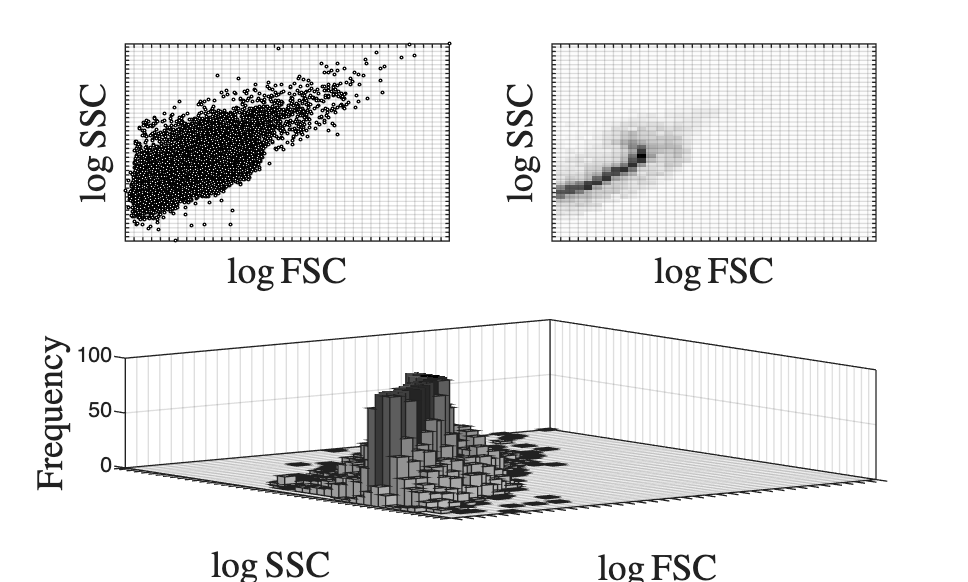


 figure(1)
 subplot(2,2,1)
 plot(FSC,SSC,'blacko','MarkerFaceColor','w','MarkerSize',1)
 xlabel('$\log \textrm{FSC}$','Interpreter','latex','FontSize',14)
 ylabel('$\log \textrm{SSC}$','Interpreter','latex','FontSize',14)
 grid on
 xticks(FSCedges)
 yticks(SSCedges)
 xticklabels('')
 yticklabels('')
 axis([minFSC maxFSC minSSC maxSSC])

figure(1)
subplot(2,2,2)
c=linspace(0.99,0,64)';
C=[c,c,c];
imagesc(FSCedges,SSCedges, freqjoint)
set(gca,'YDir','normal')
 xlabel('$\log \textrm{FSC}$','Interpreter','latex','FontSize',14)
 ylabel('$\log \textrm{SSC}$','Interpreter','latex','FontSize',14)
axis([minFSC maxFSC minSSC maxSSC])
 xticks(FSCedges)
 yticks(SSCedges)
 xticklabels('')
 yticklabels('')
colormap(C)
grid on

figure(1)
subplot(2,2,[3 4])
h=histogram2(FSC,SSC,FSCedges,SSCedges,'FaceColor','flat','Normalization','count');
set(gca,'YDir','normal')
colormap(C)
xlabel('$\log \textrm{FSC}$','Interpreter','latex','FontSize',14)
ylabel('$\log \textrm{SSC}$','Interpreter','latex','FontSize',14)
zlabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
axis([minFSC maxFSC minSSC maxSSC 0 100])
 xticks(FSCedges)
 yticks(SSCedges)
 xticklabels('')
 yticklabels('')
print -depsc -r1200 ch3_flow_cytometer_joint.eps

## Marginal pdfs (Example 3.7)

get marginal pdfs

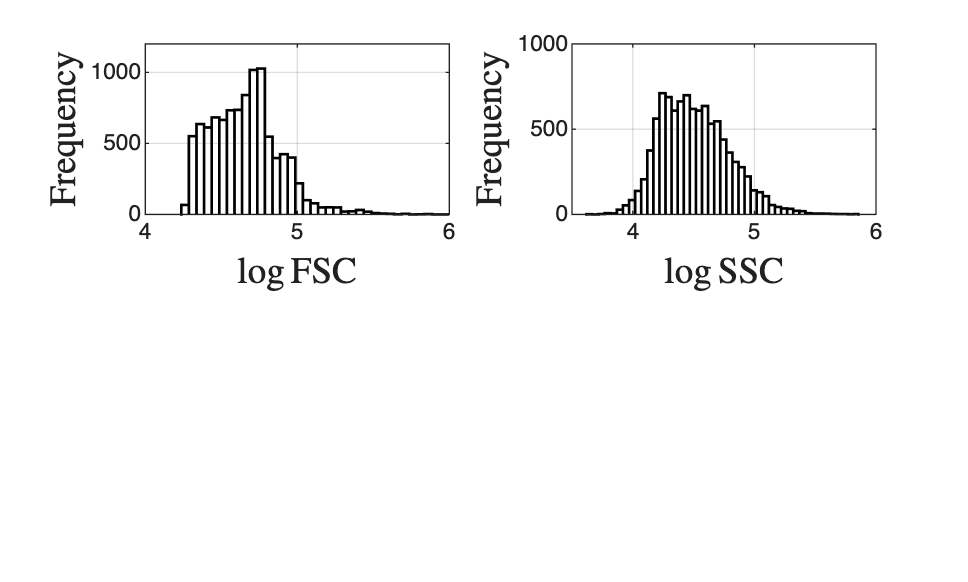

[freqSSC,SSCedges]=histcounts(SSC,'BinWidth',0.05,'BinLimits',[minSSC,maxSSC]);
[freqFSC,FSCedges]=histcounts(FSC,'BinWidth',0.05,'BinLimits',[minFSC,maxFSC]);

figure(2)
subplot(2,2,1)
histogram(FSC,FSCedges,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$\log \textrm{FSC}$','Interpreter','latex','FontSize',14)
ylabel('\textrm{Frequency}','Interpreter','latex','FontSize',14)
grid on
axis([4 6 0 1200])

subplot(2,2,2)
histogram(SSC,SSCedges,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
ylabel('\textrm{Frequency}','Interpreter','latex','FontSize',14)
xlabel('$\log \textrm{SSC}$','Interpreter','latex','FontSize',14)
grid on
axis([3.5 6 0 1000])
print -depsc ch3_flow_cytometer_marginals.eps


SSCedges

SSCedges =     3.6191    3.6691    3.7191    3.7691    3.8191    3.8691    3.9191    3.9691    4.0191    4.0691    4.1191    4.1691    4.2191    4.2691    4.3191    4.3691    4.4191    4.4691    4.5191    4.5691    4.6191    4.6691    4.7191    4.7691    4.8191    4.8691    4.9191    4.9691    5.0191    5.0691    5.1191    5.1691    5.2191    5.2691    5.3191    5.3691    5.4191    5.4691    5.5191    5.5691    5.6191    5.6691    5.7191    5.7691    5.8191    5.8543


## Note

As in the book, the joint pdf has a complex shape; the marginal pdf of FSC is nonsymmetric with a peak in [4.5, 5], while that of SSC is symmetric and Gaussian-like.